## Assignment 1 - Gabriel Garcia - COP 4401

### Step 1

An image file is selected, loaded, and its complement is taken.

img = imread(".\Horse.jpg");
imgComp = imcomplement(img);

### Step 2

Enter a blur percentage and normalize it to the width of the image.

blurPercent =50;
imgX = size(img, 2);
kernelNeighborhood = imgX * (blurPercent / 100) * 0.05; % Multiply by 0.05 to limit blur radius.

### Step 3

Apply the blur if kernel neighborhood is greater than 0.

if (kernelNeighborhood > 0)
    imgBlur = imgaussfilt(img, kernelNeighborhood, Padding='replicate');
    imgCompBlur = imgaussfilt(imgComp, kernelNeighborhood, Padding='replicate');
else % Branch is required due to imgaussfilt() not taking a kernel neighborhood of 0.
    imgBlur = img;
    imgCompBlur = imgComp;
end

### Step 4

Display the initial, intermediate, and final image. Write final image to file.

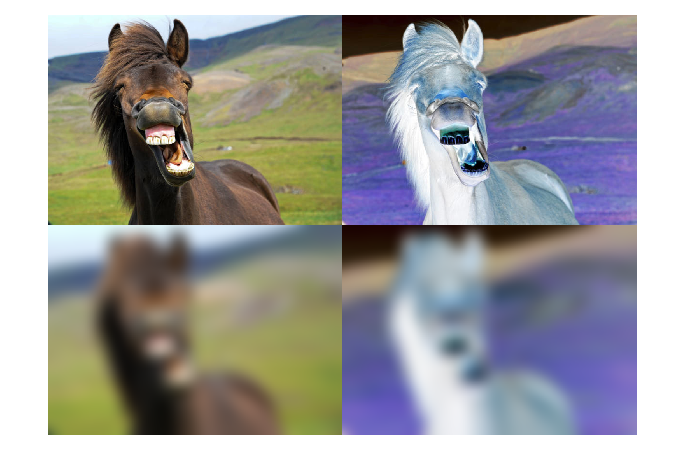

montage({img, imgComp, imgBlur, imgCompBlur})


imgFormat = "png";
imwrite(imgCompBlur, "OutputImg." + imgFormat , imgFormat);